clear all;
close all;
% TODO: Data reshaping 
% TODO: Assign the numeric representations for each cluster
% TODO: Silhouette plot to determine optimal k
% TODO: Implement replicates for kmeans
% TODO: Implement outlier detection

## In this script, you need to implement three functions as part of the k-means algorithm.

These steps will be repeated until the algorithm converges:

  % 1. initialize_centroids
  % This function sets the initial values of the centroids
  
  % 2. assign_vector_to_centroid
  % This goes through the collection of all vectors and assigns them to
  % centroid based on norm/distance
  
  % 3. update_centroids
  % This function updates the location of the centroids based on the collection
  % of vectors (handwritten digits) that have been assigned to that centroid.

## Initialize Data Set

These next lines of code read in two sets of MNIST digits that will be used for training and testing respectively.

% training set (1500 images)
train=csvread('mnist_train_1500.csv');
trainsetlabels = train(:,785);
train=train(:,1:784);
train(:,785)=zeros(1500,1);

% testing set (200 images with 11 outliers)
test=csvread('mnist_test_200_woutliers.csv');
% store the correct test labels
correctlabels = test(:,785);
test=test(:,1:784);

% now, zero out the labels in "test" so that you can use this to assign
% your own predictions and evaluate against "correctlabels"
% in the 'cs1_mnist_evaluate_test_set.m' script
test(:,785)=zeros(200,1);

## After initializing, you will have the following variables in your workspace:

1. train (a 1500 x 785 array, containins the 1500 training images) 2. test (a 200 x 785 array, containing the 200 testing images) 3. correctlabels (a 200 x 1 array containing the correct labels (numerical meaning) of the 200 test images

## To visualize an image, you need to reshape it from a 784 dimensional array into a 28 x 28 array.

to do this, you need to use the reshape command, along with the transpose operation. For example, the following lines plot the first test image

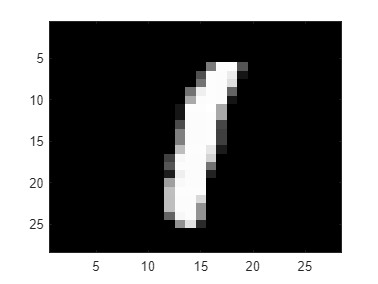

figure;
colormap('gray'); % this tells MATLAB to depict the image in grayscale
testimage = reshape(test(1, [1:784]), [28 28]);
% we are reshaping the first row of 'test', columns 1-784 (since the 785th
% column is going to be used for storing the centroid assignment.
imagesc(testimage'); % this command plots an array as an image.  Type 'help imagesc' to learn more.

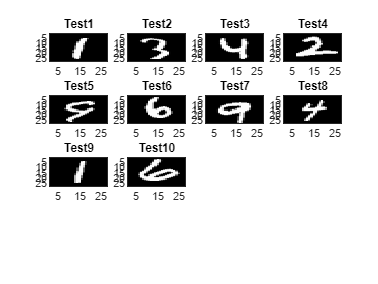




% DEBUG
plotsize=ceil(sqrt(10));
for ind=1:10
    centr=test(ind,[1:784]);
    subplot(plotsize,plotsize,ind);
    imagesc(reshape(centr,[28 28])');
    title(strcat('Test ',num2str(ind)))
end

## After importing, the array 'train' consists of 1500 rows and 785 columns.

Each row corresponds to a different handwritten digit (28 x 28 = 784) plus the last column, which is used to index that row (i.e., label which cluster it belongs to. Initially, this last column is set to all zeros, since there are no clusters yet established.

## This next section of code calls the three functions you are asked to specify

k= 15; % set k
max_iter= 2000; % set the number of iterations of the algorithm

## The next line initializes the centroids. Look at the initialize_centroids()

function, which is specified further down this file.

centroids=initialize_centroids(train,k);

## Initialize an array that will store k-means cost at each iteration

cost_iteration = zeros([max_iter,1]);

## This for-loop enacts the k-means algorithm

minK = 5;
maxK = 35;
minCosts = zeros([maxK-minK+1,1]);
accuracies = zeros([maxK-minK+1,1]);
% This is to avoid a later problem where splitapply does not accept vectors
% with 0s in them (sparse vectors). Just remember to subtract 1 from the
% group numbers to get the actual numerical value each group (index) represents
trainsetlabels = trainsetlabels + 1;
for k=minK:maxK
    
    centroids=initialize_centroids(train,k);
    cost_iteration = zeros([max_iter,1]);
    iterUsed = max_iter;
    
    for iter=1:max_iter
        
        for j=1:size(train,1)
            [index,vec_distance] = assign_vector_to_centroid(train(j,:),centroids);
            cost_iteration(iter) = cost_iteration(iter) + vec_distance;
            train(j,785) = index;
        end
        
        new_centroids = update_Centroids(train,k);
        
        if(centroids(:,1:784)==new_centroids)
            fprintf("Converged, k=%d at iteration %d\n",k,iter)
            iterUsed = iter;
            break;
        end
        
        centroids(:,1:784) = new_centroids;
    end
    

    % DANGEROUS: This assumes each number shows up at least onece in the
    % centroids. TODO: Add failsafe to this
    labelMap = splitapply(@mode,trainsetlabels,train(:,785))-1;
    disp(labelMap.')
    numCorrect = 0;
    for t=1:size(test,1)
        if(labelMap(predict(centroids,test(t,1:784)))==correctlabels(t))
            numCorrect = numCorrect + 1;
        end
    end
    accuracies(k+1-minK) = numCorrect;
    fprintf("Num Correct for k=%d: %d\n",k,numCorrect);
    minCosts(k+1-minK) = min(cost_iteration(1:iterUsed));
%     checkResults(centroids(:,1:784),test(:,1:784),correctlabels)
%     [grouping, ~] = checkResults(centroids(:,1:784),test(:,1:784),correctlabels);
end

Converged, k=5 at iteration 35


     0     3     7     6     1



Num Correct for k=5: 87


Converged, k=6 at iteration 21


     3     2     1     0     6     7



Num Correct for k=6: 93


Converged, k=7 at iteration 18


     1     3     6     4     7     2     0



Num Correct for k=7: 104


Converged, k=8 at iteration 24


     8     3     6     7     1     0     0     1



Num Correct for k=8: 96


Converged, k=9 at iteration 32


     6     6     9     7     0     1     3     1     8



Num Correct for k=9: 102


Converged, k=10 at iteration 16


     8     3     2     4     0     5     7     1     3     6



Num Correct for k=10: 127


Converged, k=11 at iteration 17


     2     1     4     7     9     7     1     0     6     6     3



Num Correct for k=11: 114


Converged, k=12 at iteration 19


     6     7     8     9     0     2     4     7     8     1     1     3



Num Correct for k=12: 129


Converged, k=13 at iteration 26


     2     1     8     4     8     3     9     0     7     6     7     1     0



Num Correct for k=13: 129


Converged, k=14 at iteration 20


     1     7     0     7     6     2     0     5     6     9     3     4     8     1



Num Correct for k=14: 136


Converged, k=15 at iteration 28


     7     0     8     0     4     3     7     6     3     2     6     1     1     8     9



Num Correct for k=15: 131


Converged, k=16 at iteration 22


     1     7     0     1     3     6     5     4     0     8     4     3     7     0     2     6



Num Correct for k=16: 126


Converged, k=17 at iteration 37


     3     7     4     6     6     0     4     2     9     0     1     5     0     7     9     1     8



Num Correct for k=17: 144


Converged, k=18 at iteration 28


     0     3     0     2     6     0     2     7     4     3     8     4     2     8     9     6     1     1



Num Correct for k=18: 130


Converged, k=19 at iteration 14


     3     7     6     1     0     4     0     7     1     6     5     5     6     3     9     2     8     0     8



Num Correct for k=19: 142


Converged, k=20 at iteration 38


     1     6     6     3     7     0     7     3     0     0     4     4     1     3     2     6     1     4     8     9



Num Correct for k=20: 128


Converged, k=21 at iteration 41


     0     0     9     6     1     7     8     6     0     4     1     5     4     3     1     2     3     3     0     8     2



Num Correct for k=21: 140


Converged, k=22 at iteration 16


     0     0     7     4     9     7     7     8     2     6     5     6     1     7     6     3     2     7     1     4     9     3



Num Correct for k=22: 129


Converged, k=23 at iteration 20


     4     5     6     6     1     3     3     9     4     6     0     0     7     4     8     2     4     7     1     8     4     3     0



Num Correct for k=23: 127


Converged, k=24 at iteration 16


  Columns 1 through 23

     9     4     7     6     8     8     5     3     0     0     7     2     0     2     1     4     1     3     1     6     7     9     4

  Column 24

     2



Num Correct for k=24: 145


Converged, k=25 at iteration 21


  Columns 1 through 23

     5     4     6     2     2     5     3     0     6     0     2     4     1     2     2     5     3     7     7     0     8     6     1

  Columns 24 through 25

     2     1



Num Correct for k=25: 137


Converged, k=26 at iteration 22


  Columns 1 through 23

     1     9     8     3     2     5     5     1     2     1     1     6     0     2     7     9     3     7     6     4     8     0     3

  Columns 24 through 26

     6     5     4



Num Correct for k=26: 149


Converged, k=27 at iteration 32


  Columns 1 through 23

     8     1     1     9     2     4     4     1     7     3     5     6     7     4     0     6     8     4     6     0     3     5     4

  Columns 24 through 27

     3     2     0     0



Num Correct for k=27: 146


Converged, k=28 at iteration 20


  Columns 1 through 23

     0     2     7     4     7     8     9     0     7     3     2     3     6     8     3     9     2     5     5     0     2     3     6

  Columns 24 through 28

     1     6     6     4     1



Num Correct for k=28: 152


Converged, k=29 at iteration 28


  Columns 1 through 23

     6     7     1     6     7     3     4     6     6     5     7     6     5     7     0     4     2     9     4     5     1     2     8

  Columns 24 through 29

     2     9     3     0     0     1



Num Correct for k=29: 137


Converged, k=30 at iteration 15


  Columns 1 through 23

     1     0     6     0     8     0     4     3     2     8     5     0     1     3     7     6     5     6     4     4     5     3     2

  Columns 24 through 30

     0     7     8     3     9     2     5



Num Correct for k=30: 147


Converged, k=31 at iteration 20


  Columns 1 through 23

     6     1     3     3     2     9     3     5     1     6     0     6     5     8     8     0     4     4     2     7     3     9     5

  Columns 24 through 31

     3     8     3     2     2     7     6     1



Num Correct for k=31: 143


Converged, k=32 at iteration 15


  Columns 1 through 23

     5     6     7     3     2     6     1     2     9     1     8     5     4     5     8     0     6     3     7     7     8     0     9

  Columns 24 through 32

     6     6     4     2     9     1     0     3     4



Num Correct for k=32: 146


Converged, k=33 at iteration 17


  Columns 1 through 23

     2     6     0     8     3     6     2     9     5     7     2     3     1     7     6     1     3     6     0     4     4     8     3

  Columns 24 through 33

     4     9     1     6     9     0     0     8     1     0



Num Correct for k=33: 145


Converged, k=34 at iteration 19


  Columns 1 through 23

     1     4     6     2     5     0     7     9     2     0     2     6     2     0     0     1     6     9     8     3     2     3     2

  Columns 24 through 34

     4     8     3     7     8     6     4     5     5     7     2



Num Correct for k=34: 146


Converged, k=35 at iteration 28


  Columns 1 through 23

     1     8     7     2     0     3     6     0     6     0     2     2     3     0     5     1     3     5     2     4     9     0     5

  Columns 24 through 35

     4     2     4     3     6     8     7     4     8     6     6     1



Num Correct for k=35: 150


%test(:,grouping(:,2)==1)
accuracies = cat(2,(minK:maxK).',accuracies)

accuracies =      5    87
     6    93
     7   104
     8    96
     9   102
    10   127
    11   114
    12   129
    13   129
    14   136


## This section of code plots the k-means cost as a function of the number of iterations

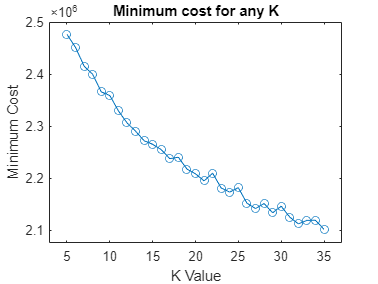

% cost_iteration
% figure;
% plot(cost_iteration(1:iterUsed),'o-')
% title("K Means Cost Function")
% xlabel("Iteration")
% ylabel("Cost")
% axis padded
figure;
plot(minK:maxK,minCosts(1:maxK-minK+1),'o-');
title("Minimum cost for any K")
xlabel("K Value")
ylabel("Minimum Cost")
axis padded

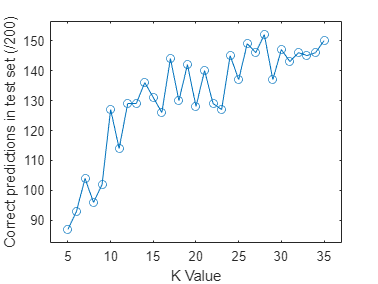

figure;
plot(accuracies(:,1),accuracies(:,2),'o-')
xlabel("K Value")
ylabel("Correct predictions in test set (/200)")
axis padded

## This next section of code will make a plot of all of the centroids

Again, use help [functionname](about:blank<#functionname>) to learn about the different functions that are being used here.

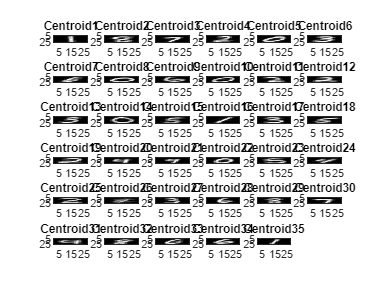

figure;
colormap('gray');

plotsize = ceil(sqrt(k));

for ind=1:k
    centr=centroids(ind,[1:784]);
    subplot(plotsize,plotsize,ind);
    
    imagesc(reshape(centr,[28 28])');
    title(strcat('Centroid ',num2str(ind)))
end

## Functions to predict results based on a set of centroids

function result=predict(centroids,point)
    % Predict result using euclidean distance
    minIndex = 1;
    for i=1:size(centroids,1)
        if(norm(centroids(i,1:784)-point)<norm(centroids(minIndex,1:784)-point(1:784)))
            
            minIndex = i;
            
        end
        
    end
    result = minIndex;
    
end
% 
% % [results, accuracy]
% function results=checkResults(centroids,points,groundtruth)
%     
%     r=ones([size(points,1),2]);
%     
%     % 1:size(points,1)
%     for j=1:200
%         r(j:2) = predict(centroids,points(j,:));
%         r(j:1) = j;
%     end
%     
%     positives = (r==groundtruth);
%     accuracy = sum(positives)/length(positives);
%     results = r;
% end

## Function to initialize the centroids

This function randomly chooses k vectors from our training set and uses them to be our initial centroids There are other ways you might initialize centroids. *Feel free to experiment.*** Note that this function takes two inputs and emits one output (y).

function y=initialize_centroids(data,num_centroids)

random_index=randperm(size(data,1));

centroids=data(random_index(1:num_centroids),:);

y=centroids;

end

## Function to pick the Closest Centroid using norm/distance

This function takes two arguments, a vector and a set of centroids It returns the index of the assigned centroid and the distance between the vector and the assigned centroid.

function [index, vec_distance] = assign_vector_to_centroid(data,centroids)
    minC = 1;
    dists = zeros([size(centroids,1),1]);
    for c=1:size(centroids,1)
        dists(c) = norm(data(1:784)-centroids(c,1:784));
        if(dists(minC)>dists(c))
            minC = c;
        end
    end
    index = minC;
    vec_distance = dists(minC);
end

## Function to compute new centroids using the mean of the vectors currently assigned to the centroid.

This function takes the set of training images and the value of k. It returns a new set of centroids based on the current assignment of the training images.

function new_centroids=update_Centroids(data,K)
    new_centroids = splitapply(@mean,data(:,1:784),data(:,785));
end